# 1. Reconstruct Doppler data to a 3D velocity map.

Dock figure(1) and use [this layout](https://docs.google.com/document/d/1RuEO2t5K-t82QPUK-sShLjorJyRC5uLGxchojfOiYDs/edit#heading=h.3m49wo5vra7y). 

**Prerequisite: Angiogram / 1 Reconstruct.**

## 10. Initiate.

Select a dataset to reconstruct. You can ignore a warning message (orange color) here. The values in the instruction below are default values. 

- pid : Process ID (processed data will be saved by this file name)

- uidA, eidA, pidA : Process ID of the corresponding angiogram.

- IX = 1, IY = 1, IZ = 1 : Mosaic numbers in Y and Z (not used yet)

comInit;

pid = 'dop-AD6-2';  % Process ID

uid = 'kwalek';  % User ID
eid = '171007_AD6';  % Experiment ID
did = 'AD6_wk14_dopp';  % Data ID
IX = 1;  IY = 1;  IZ = 1;

uidA = 'kwalek';
eidA = '171007_AD6';
pidA = 'ang-AD6-2';

pathraw = ['R:/ENG_Lee-Lab_Shared/group/data/16ThorlabsSD/' uid '/' eid];  % path of rawdata
pathdata = ['D:/' uid '/' eid];  % path to save reconstructed data
pathdataA = ['D:/' uidA '/' eidA];  % path that the reconstructed angio data was saved.

sec10;

conf = struct with fields:
             dx: 3
             dy: 3
             x0: 0
             y0: 0
          Xstep: 1.5360
          Ystep: 1.5360
          Zstep: 0.5000
         intpDk: 0.2400
         X__mm_: 1.5360
     Bscan__ms_: 189.6367
         Y__mm_: 1.5360
     Volume__s_: 15.9001
    Memory__GB_: 64
     Time__min_: 0.5300
      Data__GB_: 32
        flyback: 0.0030
             nx: 512
             ny: 512
            apx: 8
            bpy: 1
             nv: 2
             MX: 1
             MY: 1
             MZ: 1


## 11. Reconstruct and average using the parameters chosen in the angio reconstruction. [1-2 hr]

Parameters:

- pp.rmaxlag = 0 : Max timelag relative to apx for autocorrelation. 0 means Kasai.

- pp.oCOR = 1 : Remove the center of rotation? 0=no, 1=on RR, 2=on GG, 3=real(COR) on GG.

- pp.oShift = 1 : Correct the global shift? 0=no, 1=median, 2=mean.

- pp.medfsize = [3 3 3] : Kernel size of median filtering before averaging, no when [0 0 0]

- pp.gaufsize = [5 5 5] : Kernel size for Gaussian filtering after volume average, no when [0 0 0]. [5 5 5] means 1/e at px=1.

SECTION 11 RUNNING ...
11:29 loaded. 1/2 200/512
11:48 loaded. 1/2 400/512
12:05  Median filtering completed (4.1 min)


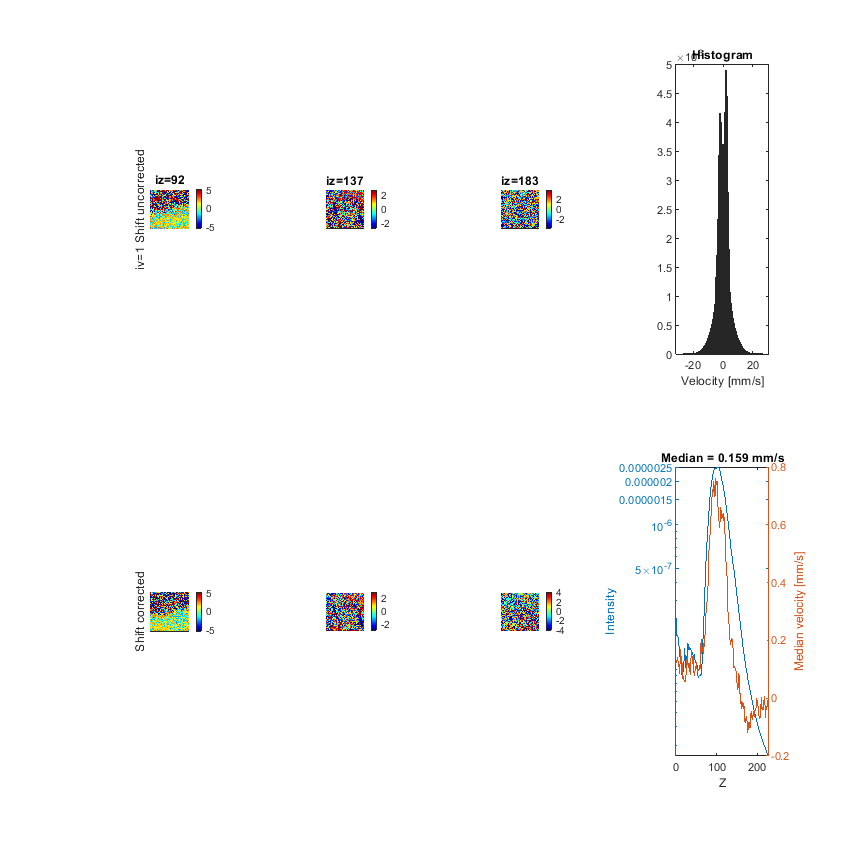

12:05  Done 1/2 meanI=5.6846e-07
12:24 loaded. 2/2 200/512
12:42 loaded. 2/2 400/512
12:59  Median filtering completed (4 min)


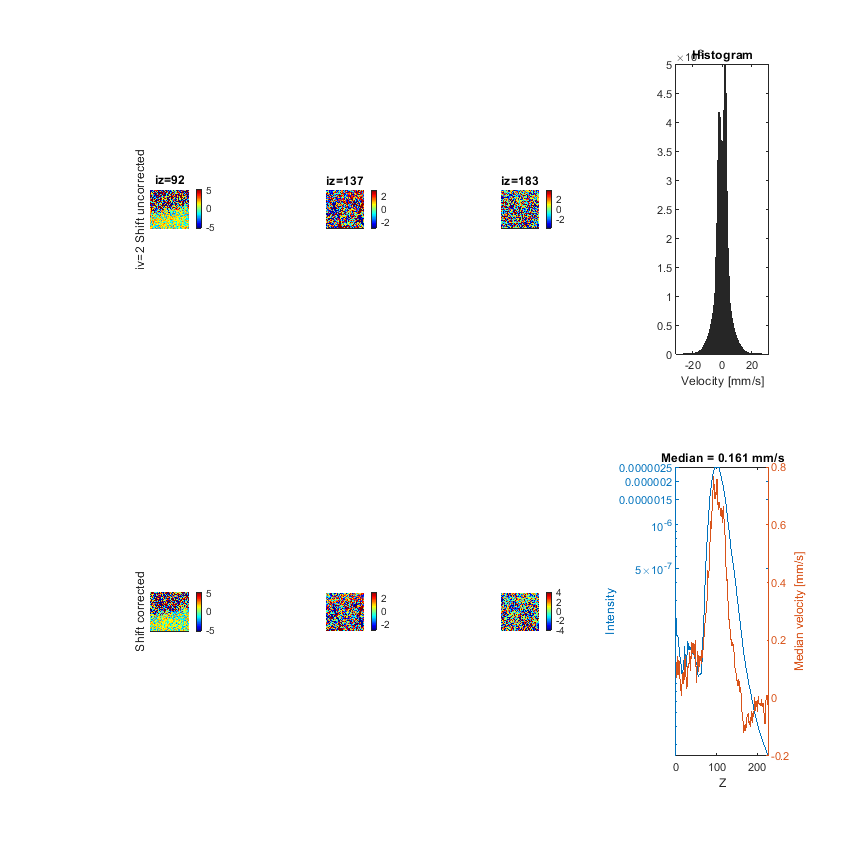

12:59  Done 2/2 meanI=5.6949e-07


Reference to non-existent field 'gaufsize'.

Error in sec11 (line 113)
    if sum(pp.gaufsize) > 0

pp.rmaxlag = 0;
pp.oCOR = 1;
pp.oShift = 1;
pp.medfsize = [3 3 3];
pp.gaufsize = [5 5 5];

pp.dk = ppA.dk;
pp.zz = ppA.zz;

sec11;

## 19. Save reconstructed data. [1-2 GB]

if ~isempty(dir([pathdata '/' pid '.mat']))
    disp(['Overwriting Data ...']);
else 
    disp('Saving Data ...');
end

Saving Data ...


clear RR1;
save('-v7.3',[pathdata '/' pid '.mat']);
disp('Data Saved.');

Data Saved.


disp(['Recommended report file name:' newline '1 Reconstruct - ' uid ' - ' eid ' - ' pid '.html']);

Recommended report file name:
1 Reconstruct - kwalek - 171007_AD6 - dop-AD6-2.html


You may also want to export this live script to a report in HTML. Run *Live Editor > Save > Export to HTML*.

**Please do *****not *****save report files under GitHub folders**. Recommened are:

- Space: *\\files.brown.edu\research\ENG_Lee-Lab_Shared\group\report\ad-16-ko-mouse\Doppler*

- You can copy the path of space and paste it into the export window.

- File name: printed above